%	Problem 1
% H-inf state feedback
% Consider the general LTI system
clear global;
A = [-5 1 0; 
	  0 1 1; 
	  1 1 1];
B1 = [0.5;
	  0;
	  0.3];
B2 = [0 0; 
	  0 1; 
	  1 0];
C = [1 0 0; 
	 0 2 1];

% a)
% Implement the H∞ LMI synthesis feasibility problem for a given attenuation level γ as
% a function and design a full state (y = x) feedback control law u = Kx such that the
% closed loop system is stable and the transfer function matrix satisfies
% ‖Gzw‖∞ < 0.5.

K = Hinf_LMI_feasy_p(A, B1, B2, C, 0, 0)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                       -0.073393

 Result:  best value of t:    -0.073393
          f-radius saturation:  0.000% of R =  1.00e+09
 


K =     2.1049   -3.9716   -2.8954
   -1.4505   -5.0618   -2.7287


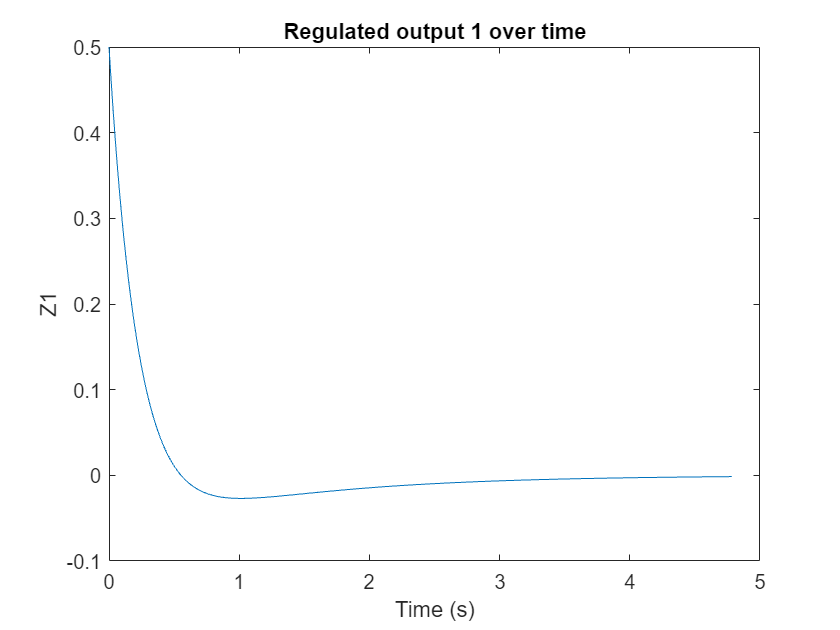


% b)
% Plot the regulated output responses z(t) to an impulse in w (use the subfigure command
% and include one signal per plot).

sys_wz = ss(A + (B2 * K), B1, C, 0);

[Z,T,X] = impulse(sys_wz);

figure();
plot(T, Z(:,1))
title("Regulated output 1 over time");
xlabel("Time (s)");
ylabel("Z1");

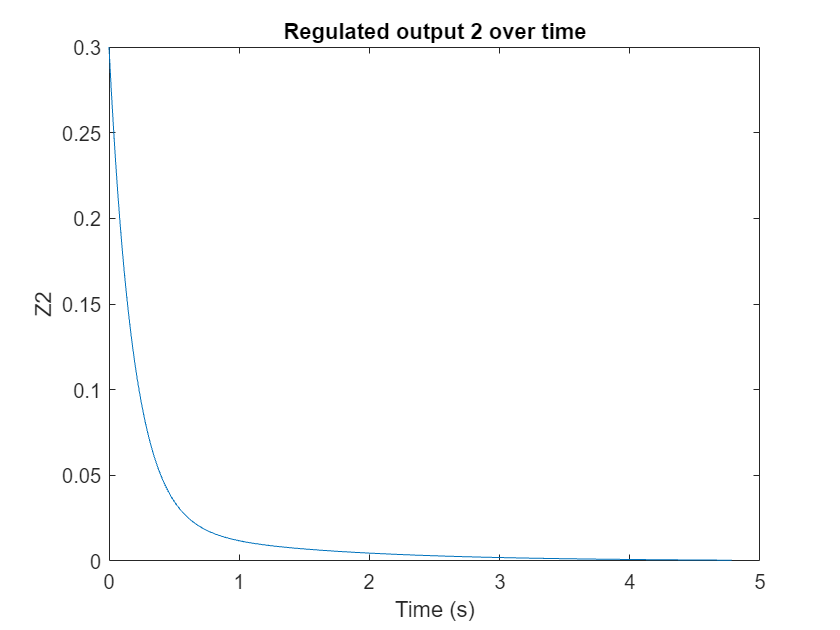


figure();
plot(T, Z(:,2))
title("Regulated output 2 over time");
xlabel("Time (s)");
ylabel("Z2");

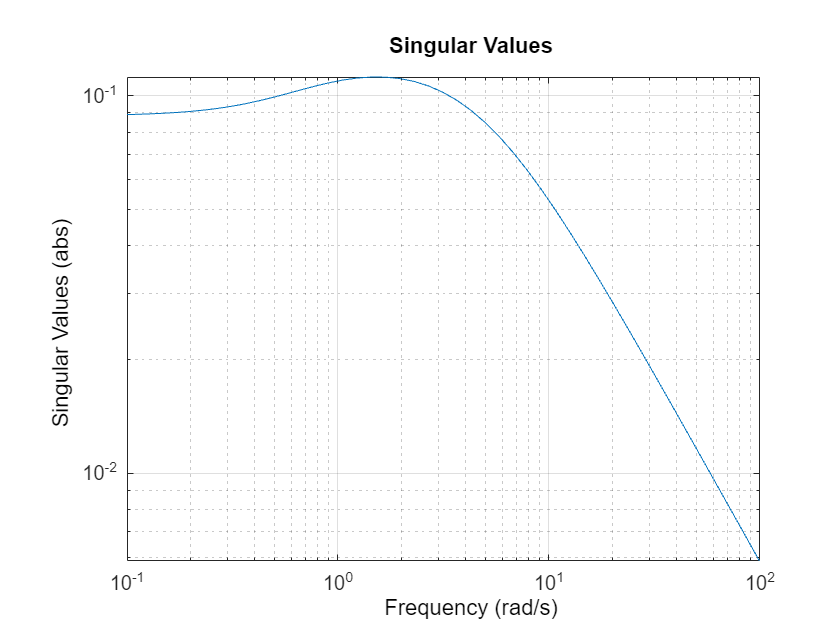


% c)
% Generate a max singular value plot of the closed loop system Gzw(s) using the command
% sigma. Does this system amplify (absolute gain > 1) or attenuate (absolute gain < 1)
% disturbances? Note that the sigma plot generates the gain in dB.

figure()
sigmaplot(sys_wz)

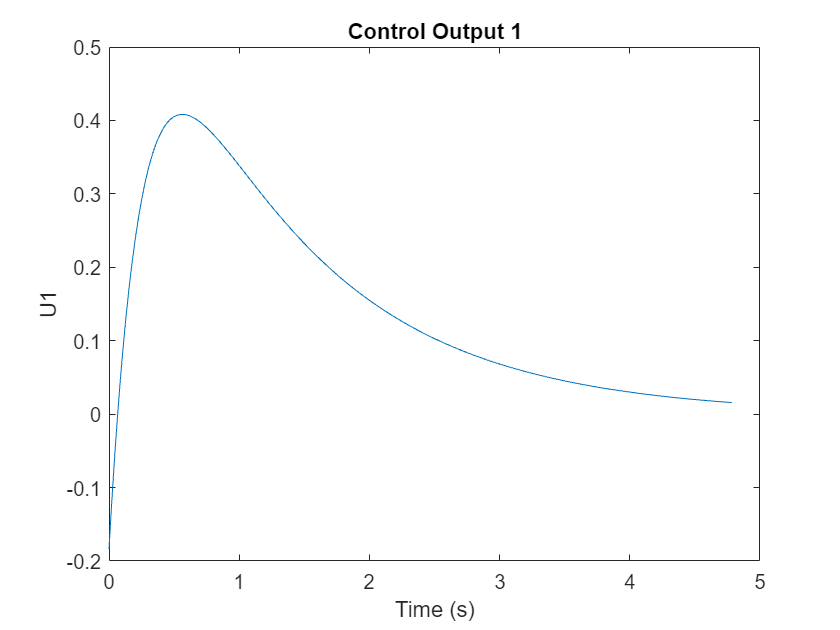


% d) 
% Plot the two control signals u1(t) and u2(t) and compute their L2 norms. Which channel
% requires more input energy?

U = X * -K';
figure()
plot(T, U(:,1))
title("Control Output 1");
xlabel("Time (s)");
ylabel("U1");

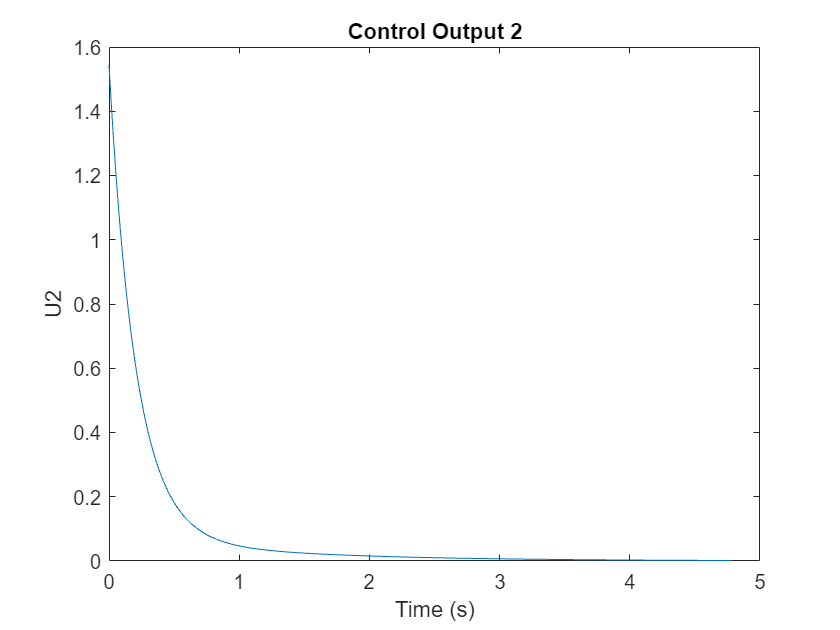


figure()
plot(T, U(:,2))
title("Control Output 2");
xlabel("Time (s)");
ylabel("U2");


fprintf("Hinf U1 norm %f", norm(U(:,1)));

Hinf U1 norm 3.367674

fprintf("Hinf U2 norm %f", norm(U(:,2)));

Hinf U2 norm 4.135326

%	Problem 2
% H-2 state feedback
% DC-8 general LTI system
% Define System Dynamics
clear global;

A = [-0.0869  0 0.039 -1 ;         % x1 = delta beta (rad)
     -4.424 -1.184 0 0.335;        % x2 = delta p (rad/s)
     0 1 0 0 ;                     % x3 = delta phi (rad)
     2.148 -0.021 0 -0.228];       % x4 = delta r (rad/s)
B1 = [0 0 0 0.288]';               % w = r_g (yaw rate gust, rad/s)
B2 = [ 0.0223 0.547 0 -1.169]';    % u1 = delta_r
C = eye(4);                       % C = I
D11 = zeros(4,1);               
D12 = [0 0 0 0]';

% a)
% Implement the H2 LMI conditions derived in lecture for the feasibility problem given
% a prescribed attenuation level ‖G(s)‖2 < γ as a function using the LMI Toolbox in
% MATLAB. Design γ for the H2 controller to match the control energy (L2 norm) for an
% equivalent H∞ controller with attenuation level γ = 2.5.
K_H2 = H2_LMI_feasy_p(A, B1, B2, C, D11)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.074298
     2                       -0.055475

 Result:  best value of t:    -0.055475
          f-radius saturation:  0.000% of R =  1.00e+09
 


K_H2 =    -8.8868    1.0178    2.2199    4.2856



% b)
% Generate the resulting singular value bode plots of the closed loop systems and the
% responses of the state x due to an impulse in the yaw disturbance rg for both the H2
% and H∞ controllers and compare both sets of plots.
K_Hinf = Hinf_LMI_feasy_p(A, B1, B2, C, 0, 0)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.105809
     2                        0.044072
     3                    9.074935e-03
     4                    9.074935e-03
     5                       -0.035978

 Result:  best value of t:    -0.035978
          f-radius saturation:  0.000% of R =  1.00e+09
 


K_Hinf =   -28.9398   10.6771   12.2423   13.3941


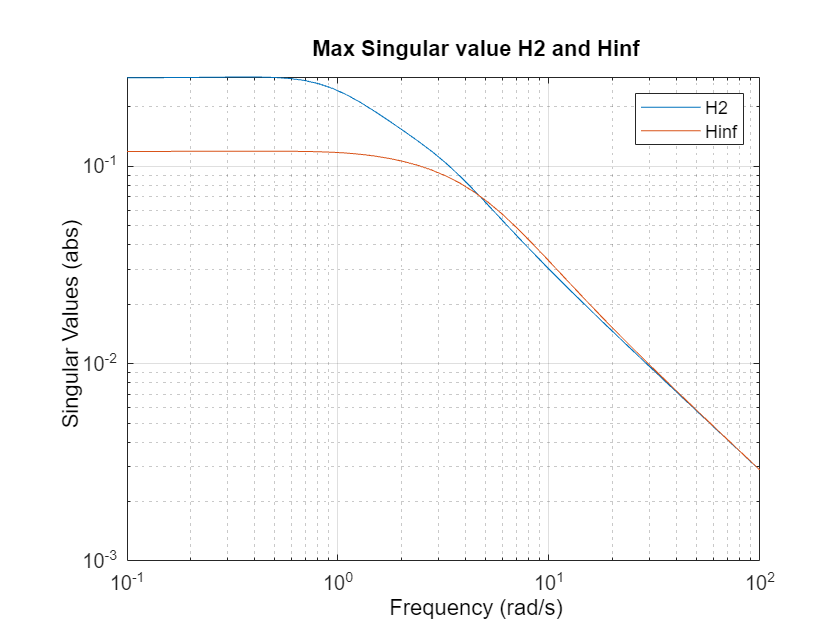


sys_wz_H2 = ss(A + (B2 * K_H2), B1, C, 0);
sys_wz_Hinf = ss(A + (B2 * K_Hinf), B1, C, 0);

figure()
hold on;
sigmaplot(sys_wz_H2)
sigmaplot(sys_wz_Hinf)
legend("H2", "Hinf")
title("Max Singular value H2 and Hinf");


% c) For a white noise yaw disturbance rg of unit intensity, compute the average power in the
% states for each of the closed loop systems and compare.

    fprintf("Average power of state  [H2]    [Hinf]");

Average power of state  [H2]    [Hinf]

for i = (1:size(A, 2))
    fprintf("                   %i: %f, %f\n", i, norm(sys_wz_H2(i), 2), norm(sys_wz_Hinf(i), 2));
end

                   1: 0.036724, 0.031283
                   2: 0.132822, 0.098753
                   3: 0.151861, 0.068890
                   4: 0.099762, 0.083213


## Problem 3

H-inf observer design

Consider the General LTI system

				
$$\dot{x} = Ax + B_2u + B_1w 

$$


				
$$z = C_1x$$


				
$$y = C_2x + D_{21}w+D_{22}u$$


with state x, measured output y, control input u, disturbance w, and the regulated outputs

z. For this system, we introduce a full-order state observer in the following form:

				
$$\dot{\hat{x}} = A\hat{x} + B_2u+L(C_2\hat{x}+D_{22}u - y)$$


where $\hat{x}$ is the state observation and L is the observer gain. The estimate of the regulated

outputs is given by $z = C_1x$, which is desired to have as small as possible influence from the

disturbance w. 

a) 

Show that for 

				
$$e(t) = x(t) - \hat{x}(t)$$


				
$$\tilde{z}(t) = z(t) - \hat{z}(t)$$


the resulting observation error equation is given by 

				
$$\dot{e} =  (A + LC_2)e+(B_1+LD_{21})w$$


				
$$\tilde{z} = C_1e$$


and has closed loop transfer function $G_{\tilde{z}w} = C_1[sI-(A+LC_2)]^{-1}(B_1+LD_{21})$

				
$$e(t) = x(t) - \hat{x}(t)$$


				
$$\dot{e}(t) = Ax + B_2u + B_1w  - A\hat{x} - B_2u - L(C_2\hat{x}+D_{22}u - y)$$


				
$$\dot{e}(t) = Ax  + B_1w  - (A+LC_2)\hat{x} - LD_{22}u + Ly$$


				
$$\dot{e}(t) = Ax  + B_1w  - (A+LC_2)\hat{x} - LD_{22}u + L(C_2x + D_{21}w+D_{22}u)$$


				
$$\dot{e}(t) = (A+LC_2)x  + B_1w  - (A+LC_2)\hat{x}+ LD_{21}w$$


				
$$\dot{e}(t) = (A+LC_2)(x- \hat{x})  + (B_1 + LD_{21})w$$


				
$$\dot{e}(t) = (A+LC_2)e  + (B_1 + LD_{21})w$$


				
$$\tilde{z}(t) = z(t) - \hat{z}(t)$$


				
$$\tilde{z}(t) = C_1x - C_1\hat{x}$$


				
$$\tilde{z}(t) = C_1e$$


b) Consider the following problem: Given the system in (a) and positive scalar $\gamma$, find a matrix L such that $||G_{\tilde{z}w}||_{\infty}<\gamma$. Prove that this problem has a solution if and only if there exists a matrix W and a positive defintie matrix P such that P > 0 and 

				
$$\pmatrix{A^TP+PA+C_2^TW^T+WC_2 & PB_1+WD_{21} & C_1^T \cr (PB_1+WD_{21})^T & -\gamma & 0 \cr C_1 & 0 & -\gamma} < 0$$


When such a pair of matrices W and P are found, the solution to the problem is given as 


$$L = P^{-1}W$$


Starting from the Hinf State Feedback LMI we can substitute


$$\pmatrix{A^TP+PA & PB & C^T \cr B^TP^T  & -\gamma & D^T \cr C & D & -\gamma} < 0$$



$$A= (A + LC_2)
$$



$$B = B_1+LD_{21}
$$



$$C = C_1$$



$$D_{11} = 0$$



$$\pmatrix{(A+LC_2)^TP+P(A+LC_2) & PB_1+PLD_{21} & C^T \cr (PB_1+PLD_{21})^T  & -\gamma & 0 \cr C & 0 & -\gamma} < 0$$



$$\pmatrix{A^TP+PA+C_2^TW^T+WC_2 & PB_1+WD_{21} & C_1^T \cr (PB_1+WD_{21})^T & -\gamma & 0 \cr C_1 & 0 & -\gamma} < 0$$


clear global;
% c)
% Design an H∞ observer according to the above approach such that ‖G ̃zw‖∞ < 0. For
% the system in Problem 1. Assume that
A = [-5 1 0; 
	  0 1 1; 
	  1 1 1];
B1 = [0.5;
	  0;
	  0.3];
B2 = [0 0; 
	  0 1; 
	  1 0];
C1 = [1 0 0; 
	 0 2 1];
C2 = [1 0 0; 
	  0 0 1];
D21 = [0 0]';

% Provide plots of the error states e1(t), e2(t) and e3(t) for 2 seconds for an impulse input
% in w.
L_Hinf = Hinf_observer_LMI_feasy_p(A, B1, C1, C2, D21)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.037035
     2                    -9.570941e-03

 Result:  best value of t: -9.570941e-03
          f-radius saturation:  0.000% of R =  1.00e+09
 


L_Hinf =     2.0623   -2.4074
   -4.5237  -15.4874
   -3.0126   -8.2320


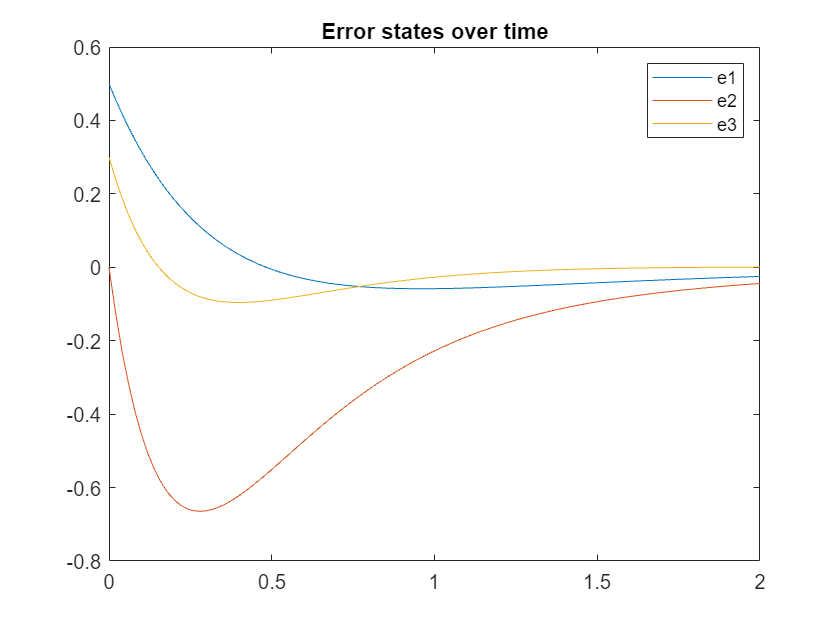


sys_observer = ss((A + L_Hinf*C2), (B1 + L_Hinf * D21), C1, 0);
[Z, T, E] = impulse(sys_observer, 2);

figure()
plot(T, E)
legend("e1", "e2", "e3")
title("Error states over time")

## Functions

function k = Hinf_LMI_feasy_p(A, B1, B2, C1, D11, D12)
    % get the input, state sizes
    % needed to define P
    n_states = size(A, 2);
    n_inputs = size(B2, 2);
    
    gamma = 0.5;

    % setup LMI expression (in the heap or sumthin)
    setlmis([])

    W = lmivar(2, [n_inputs n_states]);      % matrix
    X = lmivar(1, [n_states 1]);             % lyapunov cost to go

    lmiterm([-1, 1, 1, X], 1, 1);            % 0 < X                        [Condition 1: (1, 1)]

    lmiterm([2, 1, 1, X], A, 1, 's');        % AX + XA' < 0                 [Condition 2: (1, 1)]
    lmiterm([2, 1, 1, W], B2, 1, 's');       % AX + XA'+ W'B2'+ B2W < 0

    lmiterm([2, 1, 2, 0], B1);               % B1 < 0                       [Condition 2: (1, 2)]

    lmiterm([2, 1, 3, X'], 1, C1')           % X'C1' < 0                    [Condition 2: (1, 3)] 
    lmiterm([2, 1, 3, W'], 1, D12')          % X'C1' + W'D12' < 0

%     lmiterm([2, 2, 1, 0], B1')               % B1' < 0                      [Condition 2: (2, 1)]

    lmiterm([2, 2, 2, 0], -gamma)            % -gamma < 0                   [Condition 2: (2, 2)]

    lmiterm([2, 2, 3, 0], D11')              % D11' < 0                     [Condition 2: (2, 3)]

%     lmiterm([2, 3, 1, X], C1, 1)             % C1X < 0                      [Condition 2: (3, 1)] 
%     lmiterm([2, 3, 1, W], D12, 1)            % C1X + D12W < 0

%     lmiterm([2, 3, 2, 0], D11)               % D11 < 0                      [Condition 2: (3, 2)]

    lmiterm([2, 3, 3, 0], -gamma)            % -gamma < 0                   [Condition 2: (3, 3)]

    lmi = getlmis;

    [~,xopt] = feasp(lmi);                  % get tmin to check feasibility
    
    w = dec2mat(lmi, xopt, W);
    x = dec2mat(lmi, xopt, X);
    k = w * x^-1;
end

function k = H2_LMI_feasy_p(A, B1, B2, C, D)
    % get the input, state sizes
    % needed to define P
    n_states = size(A, 2);
    n_inputs = size(B1, 1);
    
    gamma = 2.5;
    I = eye(4);
    % setup LMI expression (in the heap or sumthin)
    setlmis([])

    Z = lmivar(1, [n_states 1]);                   % matrix
    W = lmivar(2, [1 n_inputs]);                   % matrix
    X = lmivar(1, [n_states 1]);                   % states

    lmiterm([-1, 1, 1, X], 1, 1);            % 0 < X                        [Condition 1: (1, 1)]

    lmiterm([2, 1, 1, X], A, 1, 's');        % AX + XA' < 0                 [Condition 2: (1, 1)]
    lmiterm([2, 1, 1, W], B2, 1, 's');       % AX + XA'+ W'B2'+ B2W < 0
    lmiterm([2, 1, 1, 0], B1*B1');           % AX + XA'+ W'B2'+ B2W < 0

    lmiterm([3, 1, 1, Z], -1, 1);            % -Z < 0                       [Condition 3: (1, 2)]

    lmiterm([3, 1, 2, X], C, 1)              % C1X < 0                      [Condition 3: (1, 2)] 
    lmiterm([3, 1, 2, W], D, 1)              % C1X + D12W < 0

%     lmiterm([3, 2, 1, X'], 1, C)             % X'C1' < 0                    [Condition 3: (2, 1)] 
%     lmiterm([3, 2, 1, W'], 1, D)             % X'C1 + W'D12' < 0

    lmiterm([3, 2, 2, X], -1, 1)                % -X < 0                    [Condition 3: (2, 2)]

    for i = (1:n_states)
        lmiterm([4, 1, 1, Z], I(i), I(i)');
    end
    lmiterm([-4, 1, 1, 0], gamma^2);
    
    lmi = getlmis;

    [~,xopt] = feasp(lmi);                  % get tmin to check feasibility
    
    w = dec2mat(lmi, xopt, W);
    x = dec2mat(lmi, xopt, X);
    k = w * x^-1;
end

function l = Hinf_observer_LMI_feasy_p(A, B1, C1, C2, D)
    % get the input, state sizes
    % needed to define P
    n_states = size(A, 2);
    n_outputs = size(C2, 1);
    
    gamma = 0.1;

    % setup LMI expression (in the heap or sumthin)
    setlmis([])

    W = lmivar(2, [n_states n_outputs]);      % matrix
    X = lmivar(1, [n_states 1]);             % lyapunov cost to go

    lmiterm([-1, 1, 1, X], 1, 1);            % 0 < X                        [Condition 1: (1, 1)]

    lmiterm([2, 1, 1, X], A', 1, 's');       % A'X + XA < 0                 [Condition 2: (1, 1)]
    lmiterm([2, 1, 1, W], 1, C2, 's');       % A'X + XA + W'C2'+ WC2 < 0

    lmiterm([2, 1, 2, X], 1, B1);            % XB1 < 0                      [Condition 2: (1, 2)]
	lmiterm([2, 1, 2, W], 1, D);             % XB1 + WD12 < 0

    lmiterm([2, 1, 3, X'], 1, C1')           % C1' < 0                      [Condition 2: (1, 3)] 

    lmiterm([2, 2, 2, 0], -gamma)            % -gamma < 0                   [Condition 2: (2, 2)]
% 	lmiterm([2, 2, 3, 0], 0)                 % 0 < 0                        [Condition 2: (2, 2)]
    lmiterm([2, 3, 3, 0], -gamma)            % -gamma < 0                   [Condition 2: (3, 3)]

    lmi = getlmis;

    [~,xopt] = feasp(lmi);                  % get tmin to check feasibility
    
    w = dec2mat(lmi, xopt, W);
    x = dec2mat(lmi, xopt, X);
    l = x^-1 * w;
end